# 基于从simulink-UE环境中直接输出图像+sensor 位姿真值可视化

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-08-01 11:23:16

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 23);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timeStamp", "egoVelocity", "poseEgoInGlobalWorld_1", "poseEgoInGlobalWorld_2", "poseEgoInGlobalWorld_3", "positionRotationEgoInGloableWorld_1", "positionRotationEgoInGloableWorld_2", "positionRotationEgoInGloableWorld_3", "positionRotationEgoInGloableWorld_4", "positionRotationEgoInGloableWorld_5", "positionRotationEgoInGloableWorld_6", "ultrasonicData_1", "ultrasonicData_2", "ultrasonicData_3", "ultrasonicData_4", "ultrasonicData_5", "ultrasonicData_6", "ultrasonicData_7", "ultrasonicData_8", "ultrasonicData_9", "ultrasonicData_10", "ultrasonicData_11", "ultrasonicData_12"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "timeStamp", "TrimNonNumeric", true);
opts = setvaropts(opts, "timeStamp", "ThousandsSeparator", ",");

% Import the data
sensorData = readtable("E:\AllDataAndModels\underParkingLotImages20220728\离车位近\binAndImgFromSimOutMat\sensorData.csv", opts)

sensorData = 1187×23 table
    timeStamp    egoVelocity    poseEgoInGlobalWorld_1    poseEgoInGlobalWorld_2    poseEgoInGlobalWorld_3    positionRotationEgoInGloableWorld_1    positionRotationEgoInGloableWorld_2    positionRotationEgoInGloableWorld_3    positionRotationEgoInGloableWorld_4    positionRotationEgoInGloableWorld_5    positionRotationEgoInGloableWorld_6    ultrasonicData_1    ultrasonicData_2    ultrasonicData_3    ultrasonicData_4    ultrasonicData_5    ultrasonicData_6    ultrasonicData_7    ultrasonicData_8    ultrasonicData_9    ultrasonicData_10    ultrasonicData_11    ultrasonicData_12

## Clear temporary variables

clear opts


提取车辆传感器位姿真值数据

sensorData = sensorData(3:end,:);

vehiclePose = sensorData{:,6:11};


绘制相机姿态图

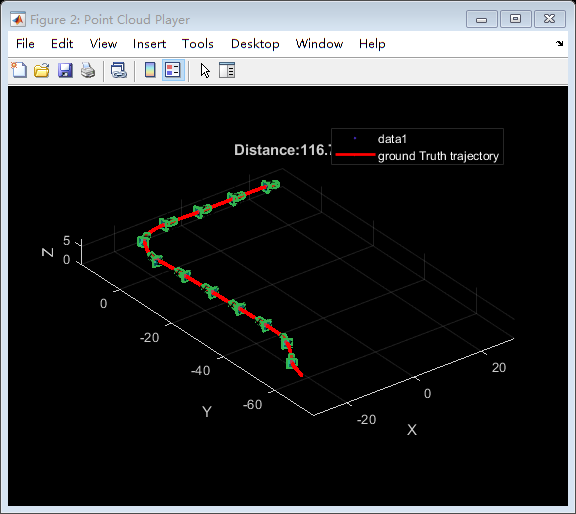

xLim = [-30,30]; % 看仿真数据的实际范围估计
yLim = [-75,15]; % 看仿真数据的实际范围
zLim = [0,7];
MapPointsPlot = pcplayer(xLim, yLim, zLim,'MarkerSize', 5);
hold(MapPointsPlot.Axes,'on');

% Plot camera trajectory
trajectory = vehiclePose(:,1:3);
plot3(MapPointsPlot.Axes, trajectory(:,1), trajectory(:,2), ...
    trajectory(:,3), 'r.-', 'LineWidth', 2 , 'DisplayName', 'ground Truth trajectory');

cameraExtrinsics = [];% numImgs*16,齐次矩阵按行展开形式
nums = height(vehiclePose);
for i = 1:nums
    currPos = vehiclePose(i,1:3);
    currPose = rad2deg(vehiclePose(i,4:6));

    R_ = rotz(currPose(3))*roty(currPose(2))*rotx(currPose(1));
    % 默认相机绘图姿态plotCamera函数方向是Z轴竖直向上，而转换基准是以x轴正向的。通用矩阵形式，非cv工具箱形式。
    R = R_*roty(90)*rotz(-90);
    t = currPos;
    cameraAbsolutePose = rigid3d(R',t);

    % 徐庆华要的yaml格式
    cameraRT = R';
    cameraOneColum = cameraRT(:);% 16*1
    cameraExtrinsics = [cameraExtrinsics;cameraOneColum'];

    % 画图
    if mod(i,100)==1
        plotCamera('AbsolutePose',cameraAbsolutePose,...
            'Parent', MapPointsPlot.Axes, 'Size', 1.2,...
            'Color',[0.2,0.7,0.3],'Opacity',0.3,'AxesVisible',true);
    end
     drawnow limitrate
end
allDistances = sum(vecnorm(diff(trajectory),2,2));
% aveSpeed = allDistances/seconds(simData.Time(end));
titleStr = sprintf("Distance:%.2f m",allDistances);
title(MapPointsPlot.Axes,titleStr);
legend(MapPointsPlot.Axes,'TextColor','white','Location','northeast');

徐庆华需要的外参形式

%% 齐次矩阵，以yml格式保存
% 先导出csv，再opencv c++读取保存为yml格式，导出参考yamlExtrinsicOutput.cpp
writematrix(cameraExtrinsics,'cameraExtrinsics.csv');
